# Fin Flutter Analysis

clear all

## **Variables**

#### **Geometry:**

Root Chord:

Cr = 9.75; %inches
Crm = Cr*25.4;%mm

Tip Chord:

Ct = 3.75; %inches
Ctm = Ct*25.4; %mm

Semi-Span: (height from body tube to tip)

b = 4.75; %inches
bm = b*25.4; %mm

#### Material/Vehicle Properties:

Shear Modulus:

G = 380000; %psi
Gm = G*6.8947572931e-6; %GPa

Thickness:

t = 0.125; %inches
tm = t*25.4; %mm

Elevation:

h = 0:100:30000; %ft
hm = h/3.281; %m

Ambient Temperature

T = 290; %Kelvin

## Calculations

S = 0.5*(Crm+Ctm)*bm;
lambda = Ctm/Crm;
g = 9.81; %m/s^2 
M = 0.02896; % kg/mol for air
R = 8.314; %(kg*m^2)/(s^2*K*mol)
H = 8077%(R*T)/(M*g); %m scale height

H =         8077


Cso = sqrt(1.4*T*287.7); %m/s speed of sound at sea level 
Po = .000101325; %GPa pressure at sea level 
B = bm^2/S; %aspect ratio 
NT = tm/Crm; %mm/mm normalized thickness
Vf = 1.223*Cso*exp(0.4*hm/H)*sqrt(Gm/Po)*sqrt((2+B)/1+lambda)*(NT/B)^(3/2)

Vf =        290.46        290.9       291.34       291.78       292.22       292.66        293.1       293.55       293.99       294.43       294.88       295.32       295.77       296.22       296.66       297.11       297.56       298.01       298.46       298.91       299.36       299.81       300.27       300.72       301.18       301.63       302.09       302.54          303       303.46       303.92       304.37       304.83       305.29       305.76       306.22       306.68       307.14       307.61       308.07       308.54          309       309.47       309.94       310.41       310.87       311.34       311.81       312.29       312.76


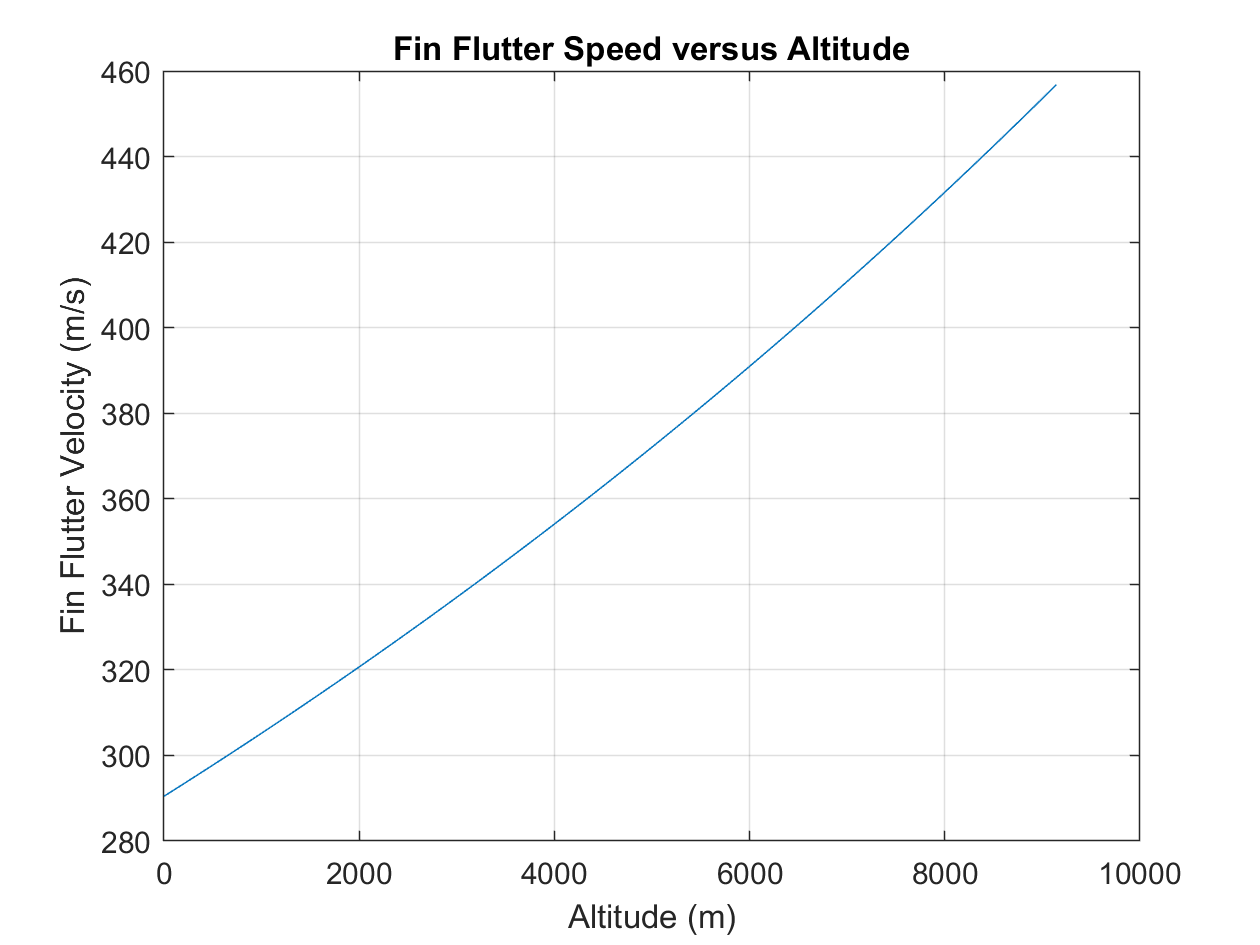

plot(hm,Vf)
ylabel 'Fin Flutter Velocity (m/s)'
xlabel 'Altitude (m)'
title 'Fin Flutter Speed versus Altitude'
grid on

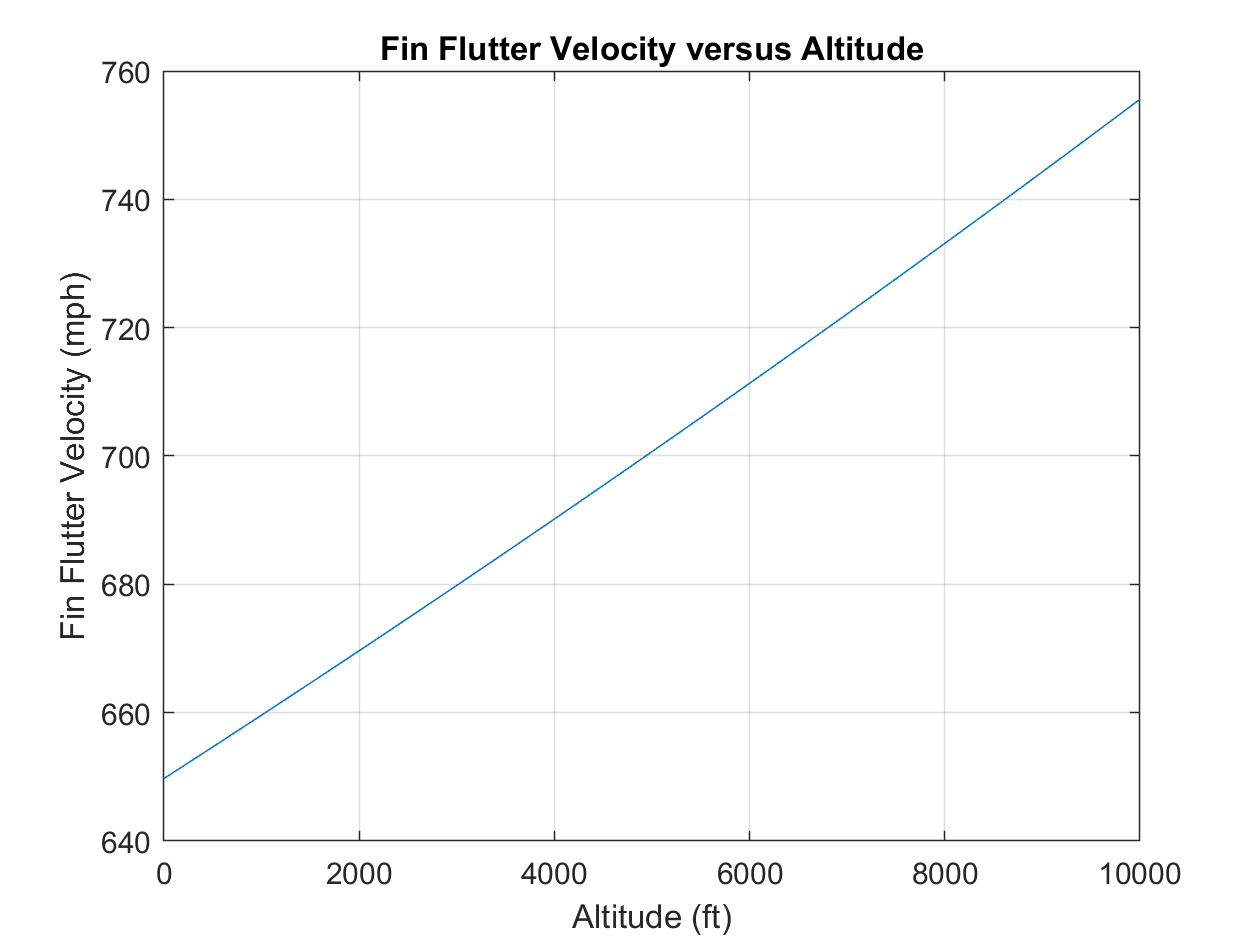

plot(hm*3.28084,Vf*2.23694)
xlim([0 10000])
xlabel 'Altitude (ft)'
ylabel 'Fin Flutter Velocity (mph)'
grid on
title 'Fin Flutter Velocity versus Altitude'

height = find(h == 3000); %index of height in feet
Vf(height) %m/s

ans =        303.92


Vf(height)*2.23694 %mph

ans =        679.84
